# **Figure 2:  BTSP correlates the connectivity in a recurrent network with past explored environments **  

### Fig B: Generating weight matrix before and after learning.

**Simulation protocol**: simulate the weight matrix of $N$ ca3 neurons over $n$ distinct environment, which mimic the animal exploring new environments. we store the weight matrix at $n-1$ environment as $W^{Bef}$ (matrix is sorted w.r.t. cell id in environment $n$) and $W^{Aft}$ (with same ordering) is the weight matrix due the learning at environment $n$. 

Export figure setup:: 3 - 3

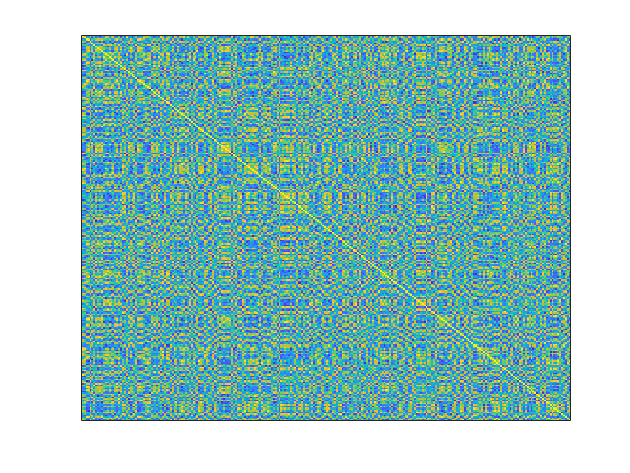

load(fullfile(read_output_dir(), "\Fig2\weight.mat"));
last_env = Env_track(:, end);
weight_before_learning = weight_before(last_env, last_env);
weight_after_learning = final_weight(last_env, last_env);

imagesc(weight_before_learning)
set(gca,'TickLength',[0 0])
xticklabels("")
yticklabels("")

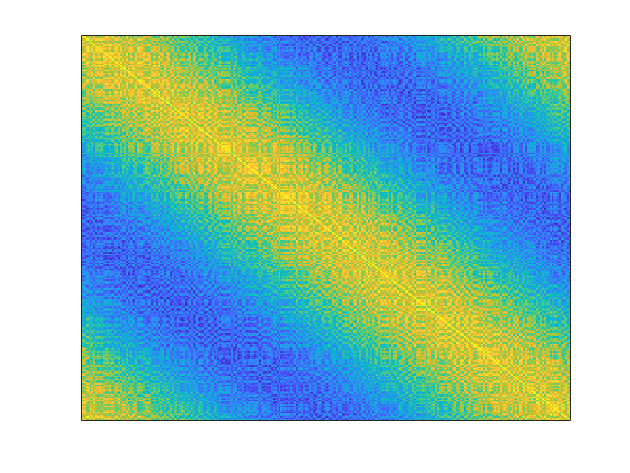

imagesc(weight_after_learning)
set(gca,'TickLength',[0 0])
xticklabels("")
yticklabels("")

### FigD: Global statistics of the connectivity matrix

For each iteration of 1D map, we already saved overall mean and overall variance of the weight matri, later are plotted to comprare the theoretical mean and variance.

Export figure setup: 4 - 3

inkscape size: 45-37.5

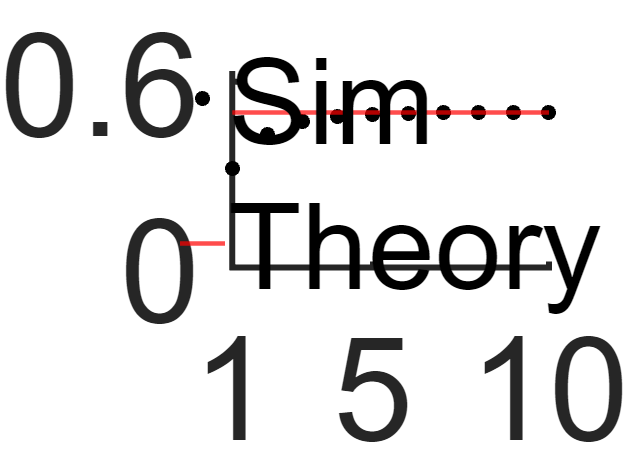

plot(1:10, weight_mean(1:10), ".k", "MarkerSize", 30)
theoretical_mean = P/(P+D);
yline(theoretical_mean, "-r", "LineWidth", 3)
ylim([0, theoretical_mean*1.25])
yticks([0, floor(theoretical_mean*1.25 *10)/10])
xlim([1, 10])
xticks([1,5, 10])
box off
legend(["Sim", "Theory"], "Location","best")
legend boxoff
fig_config(80)

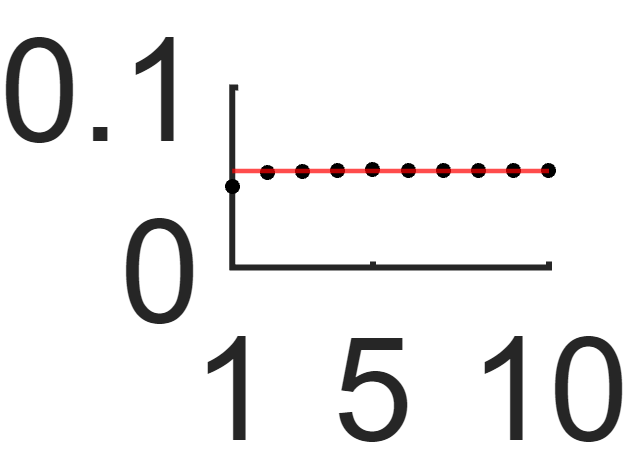



plot(1:10, weight_var(1:10), ".k", "MarkerSize", 30)
theoretical_var = 2 * P^2 * D^2 / (P+D)^2 / (2 * (P*D + P + D) - 3/2 * (P+D)^2);
yline(theoretical_var, "r", "LineWidth", 3)
ylim([0, theoretical_var *1.25])

ylim([0, 0.1])
yticks([0, 0.1])
xlim([1, 10])
xticks([1,5, 10])
box off
fig_config(80)

### FigE: Representation of weight matrix in different environment

After the connectivity matrix reaches the steady state, we represent the weight w.r.t. previous environments by sorting. The x-axis represent the phase difference in each environment. 

Therefore, we compute spatial mean and variance within each environment. 

Export figure setup: 4.5 - 3

inkscape size: 45-37.5

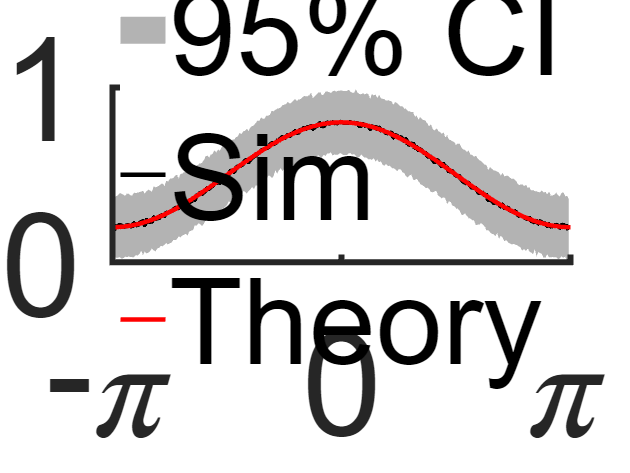

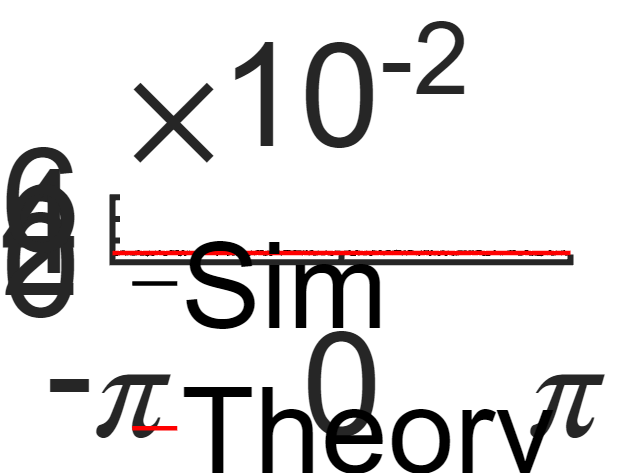

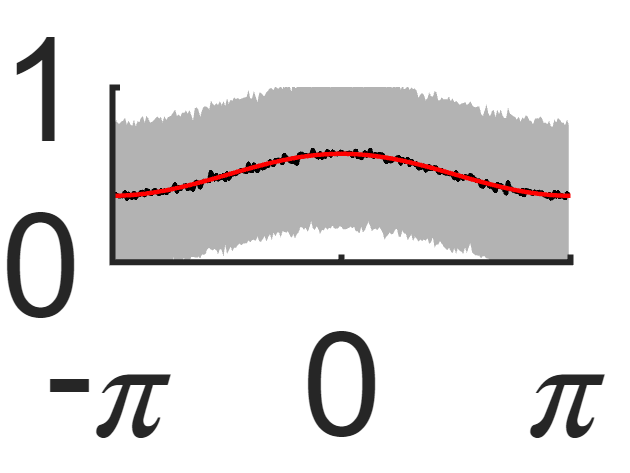

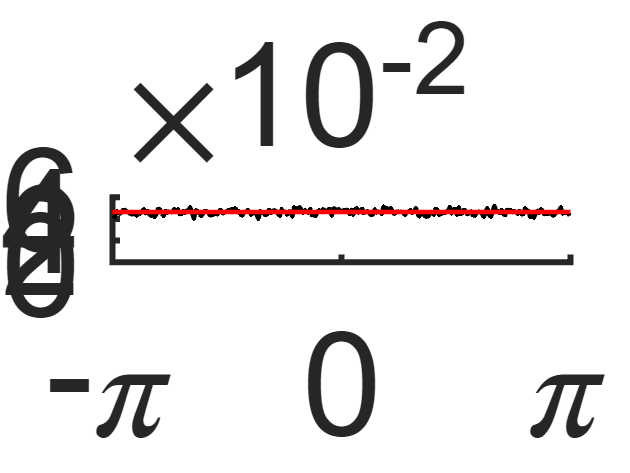

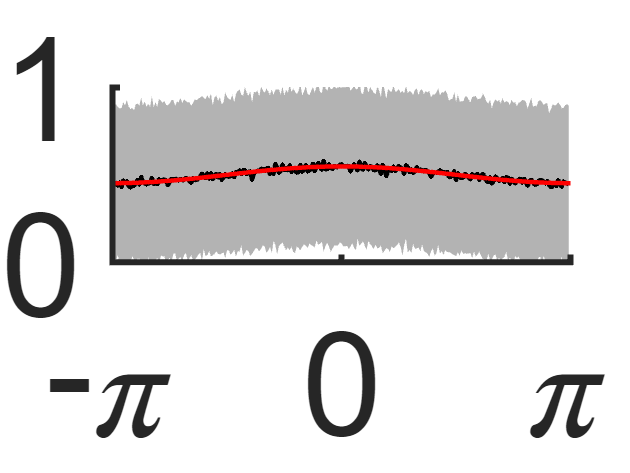

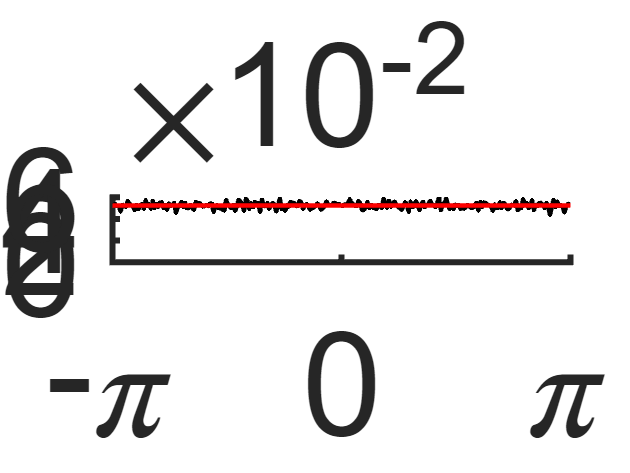

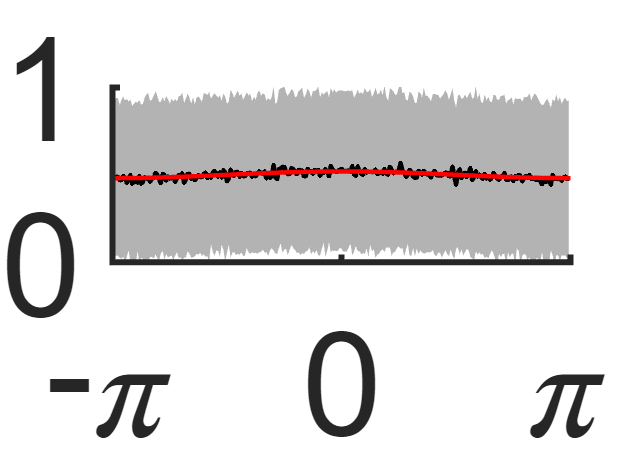

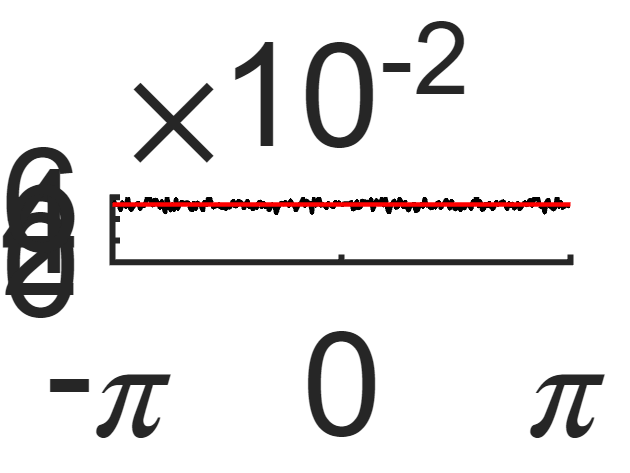

plot_mean_variance_curve(final_weight, Env_track, N, phase, ...
    P, D, M, s)

## Auxiliar function

function plot_mean_variance_curve(final_weight, Env_track, n_ca3_per_track, phase, ...
    P, D, M, s)
    is_stack = false;
    for k = [0, 1, 2, 3]
        rng(1997)
        [theo_mean, theo_var, theo_phase] = Compute_mean_variance(P, D, k, is_stack, M, s);
        [sort_weight_k, phase_modf] = Aligment(final_weight, Env_track, k, phase, n_ca3_per_track, M, s, is_stack);
        mean_weight = mean(sort_weight_k);
    
        % Since the phase for each cell to itself is always 0, then the
        % plasticty rule we defined before only remains the potentiation
        % part because the depression is always 0. 
        % To avoid the ugly representation of weight, we have either delete
        % the autolop point or smooth the autoconnection weight and also
        % the variance. 
        modified_weight = mean_weight;
        ind_logic = abs(phase_modf) < 0.3 & phase_modf ~= 0;
        attach_weight = mean_weight(ind_logic);
        modified_weight(abs(phase_modf) < 0.1) = normrnd(mean(attach_weight), std(attach_weight)/5, 1, ...
            length(modified_weight(abs(phase_modf) < 0.1)));

        noise = sort_weight_k - mean_weight;
        var_sim = var(noise);
        attach_var = var_sim(abs(phase_modf) < 0.3 & phase_modf ~= 0);
        var_sim(abs(phase) < 0.1) = normrnd(mean(attach_var), std(attach_var)/5, 1, length(var_sim(abs(phase) < 0.1)));
        
        upper_band = modified_weight + sqrt(var_sim) * 1.96;
        lower_band = modified_weight - sqrt(var_sim) * 1.96;
        figure
        h1 = fill([phase_modf', fliplr(phase_modf')], [upper_band, lower_band], [.7,.7,.7], ...
            'EdgeColor','none', 'FaceAlpha', 1);
        hold on
        plot(phase_modf, modified_weight, "k", "LineWidth", 3)
        plot(theo_phase, theo_mean, "r", "LineWidth", 3)
        hold off
        box off
        xlim([-pi, pi])
        xticks([-pi, 0, pi])
        xticklabels("")
        xticklabels(["-\pi", 0, "\pi"])
        ylim([0, 1])
        yticks([0, 1])

        if k == 0
            legend("95% CI", "Sim", "Theory", "location", "best");
            legend boxoff
        end
%{        
        if k == 0
            legend("95% CI", "Sim", "M_0", "location", "northeast");
            legend boxoff
        elseif k == 1
            hold on
            qw{1} = plot(nan, "r-", "LineWidth", 4);
            legend([qw{:}], {'M_1'}, "location", "northeast")
            legend boxoff
            hold off
        elseif k == 2
            hold on
            qw{1} = plot(nan, "r-", "LineWidth", 4);
            legend([qw{:}], {'M_2'}, "location", "northeast")
            legend boxoff
            hold off
        end
%}        
        fig_config(80)
        
        figure
        plot(phase, var_sim, "k", "LineWidth", 3)
        hold on
        plot(theo_phase, theo_var, "r", "LineWidth", 3)
        hold off
        box off
        xlim([-pi, pi])
        xticks([-pi, 0, pi])
        xticklabels(["-\pi", 0, "\pi"])
        
        aux = mean(var_sim);
        ylim([0, 0.06])
        yticks([0, 0.02, 0.04, 0.06])
        ax=gca; ax.YAxis.Exponent = -2;
        if k == 0
            legend(["Sim", "Theory"], "Location","northeast")
            legend boxoff
        end
%{        
        if k == 0
            legend(["Sim", "V_0"], "Location","northeast")
            legend boxoff
        elseif k == 1
            hold on
            qw{1} = plot(nan, "r-", "LineWidth", 4);
            legend([qw{:}], {'V_1'}, "location", "southeast")
            legend boxoff
            hold off
        elseif k == 2
            hold on
            qw{1} = plot(nan, "r-", "LineWidth", 4);
            legend([qw{:}], {'V_2'}, "location", "southeast")
            legend boxoff
            hold off
        end
%}        
        fig_config(80) 
    end
end